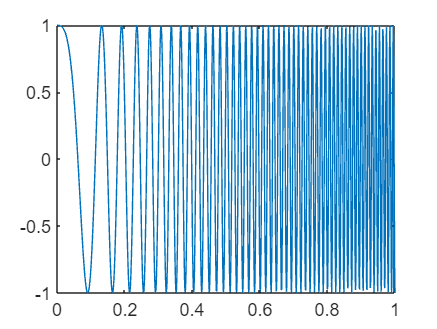

x = linspace(0,1,1000);
f1 = 2;
f2 = 10;
% y1 = sin(f1.*x);
% y2 = sin(f2.*x);
fs = 1;
y1 = chirp(x,1*fs);
y2 = chirp(x,50*fs);
plot(x,y1);

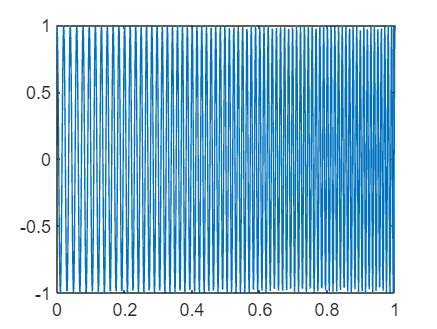

plot(x,y2);

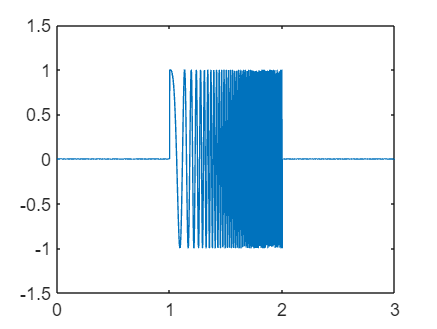

n_0 = randn(1,3000);
A = 5e-5;
y1_n = [zeros(1,1000),y1,zeros(1,1000)]+A*n_0;
y2_n = [zeros(1,1000),y2,zeros(1,1000)]+A*n_0;
x_n = linspace(0,3,3000);
plot(x_n,y1_n);

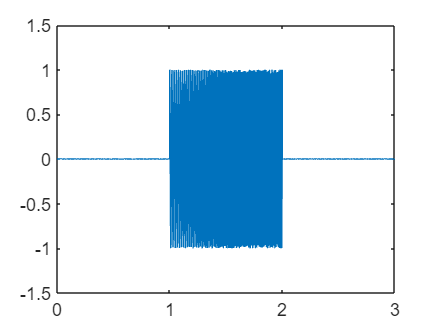

plot(x_n,y2_n);

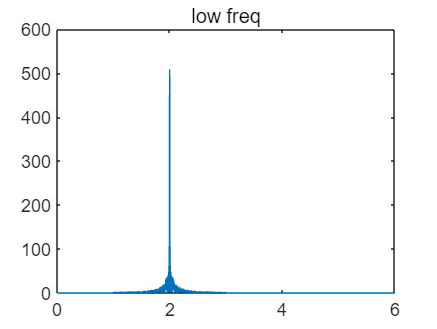

crr_y1 = xcorr(y1,y1_n);
crr_y2 = xcorr(y2,y2_n);
crr_x = linspace(0,6,length(crr_y2));
plot(crr_x,abs(crr_y1));
title("low freq")

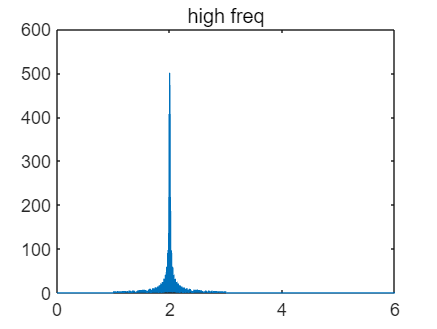

plot(crr_x,abs(crr_y2));
title('high freq')